% Variables
wedge_angle = [2.7, 3.07, 11.5, 0, 13.9];

x_23 = 1.83;
Y = 0.2225;
x_2 = x_23 - Y / tan(deg2rad(11.5));
x_3 = x_23 - x_2;

x = [3.66, x_2, x_3, 0.762, 1.068];
AoA_sweep = linspace(-2, 16, 19);
M_inf = 7;

% General Constants
gamma = 1.362;
T_inf = 225.5; % K
P_inf = 1397; % Pa
V_inf = 2107; % m/s
altitude = 28974; % m

for j = 1:length(AoA_sweep)

    for i = 1:length(wedge_angle)

        if i == 1
            % Stage 1
            if AoA_sweep(j) <= wedge_angle(i)
                theta = (wedge_angle(i) - AoA_sweep(j));
                [P_2, T_2, M2, beta] = oblique(theta, M_inf, P_inf, T_inf, gamma);
                M(i) = M2;
                T(i) = T_2;
                P(i) = P_2;
            elseif AoA_sweep(j) > wedge_angle(i)
                theta = (AoA_sweep(j) - wedge_angle(i));
                [P_2, T_2, M2] = PM_sol(theta, M_inf, P_inf, T_inf, gamma);
                M(i) = M2;
                T(i) = T_2;
                P(i) = P_2;
            end

            L(i) = P(i) * cos(deg2rad(AoA_sweep(j) - wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
            D(i) = P(i) * sin(deg2rad(AoA_sweep(j) - wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
        elseif i == 2
            % Stage 2
            if AoA_sweep(j) < 0 && abs(AoA_sweep(j)) > wedge_angle(i)
                theta = (wedge_angle(i) + AoA_sweep(j));
                [P_2, T_2, M2] = PM_sol(theta, M_inf, P_inf, T_inf, gamma);
                M(i) = M2;
                T(i) = T_2;
                P(i) = P_2;
            else
                theta = (AoA_sweep(j) + wedge_angle(i));
                [P_2, T_2, M2, beta] = oblique(theta, M_inf, P_inf, T_inf, gamma);
                M(i) = M2;
                T(i) = T_2;
                P(i) = P_2;
            end

            L(i) = P(i) * cos(deg2rad(AoA_sweep(j) + wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
            D(i) = P(i) * sin(deg2rad(AoA_sweep(j) + wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
        elseif i == 3
            % Stage 3
            theta = (wedge_angle(i) - wedge_angle(i - 1));
            [P_2, T_2, M2, beta] = oblique(theta, M(i - 1), P(i - 1), T(i - 1), gamma);
            M(i) = M2;
            T(i) = T_2;
            P(i) = P_2;

            L(i) = P(i) * cos(deg2rad(AoA_sweep(j) + wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
            D(i) = P(i) * sin(deg2rad(AoA_sweep(j) + wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
        elseif i == 4
            % Stage 4
            theta = (wedge_angle(i - 1));
            [P_2, T_2, M2] = PM_sol(theta, M(i - 1), P(i - 1), T(i - 1), gamma);
            M(i) = M2;
            T(i) = T_2;
            P(i) = P_2;

            L(i) = P(i) * cos(deg2rad(AoA_sweep(j) + wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
            D(i) = P(i) * sin(deg2rad(AoA_sweep(j) + wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
        elseif i == 5
            % Stage 5
            theta = (wedge_angle(i - 1) + wedge_angle(i));
            [P_2, T_2, M2] = PM_sol(theta, M(i - 1), P(i - 1), T(i - 1), gamma);
            M(i) = M2;
            T(i) = T_2;
            P(i) = P_2;

            L(i) = P(i) * cos(deg2rad(AoA_sweep(j) - wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
            D(i) = P(i) * sin(deg2rad(AoA_sweep(j) - wedge_angle(i))) * (x(i) / cos(deg2rad(wedge_angle(i))));
        end

        end

        Lift(j) = sum(L(2:5)) - L(1);
        Drag(j) = sum(D(2:5)) - D(1);


        for ii = 1:length(wedge_angle)
            if ii < 3
                moment(ii) = L(ii) * 0.5 * (x(ii) / cos(deg2rad(wedge_angle(ii))));
            elseif ii >= 3
                moment(ii) = L(ii) * 0.5 * (x(ii) / cos(deg2rad(wedge_angle(ii)))) + sum(x(2:ii));
            end
        end
        Moment(j) = moment(1) - (moment(2) + moment(3) + moment(4) + moment(5));
          
        LC(j) = Moment(j) / Lift(j);
        CG = 1.83;
        SM(j) = (LC(j) - CG) / x(1);
        

end


% output = [AoA_sweep', Lift', Drag', LC', SM', Cl_Cd];

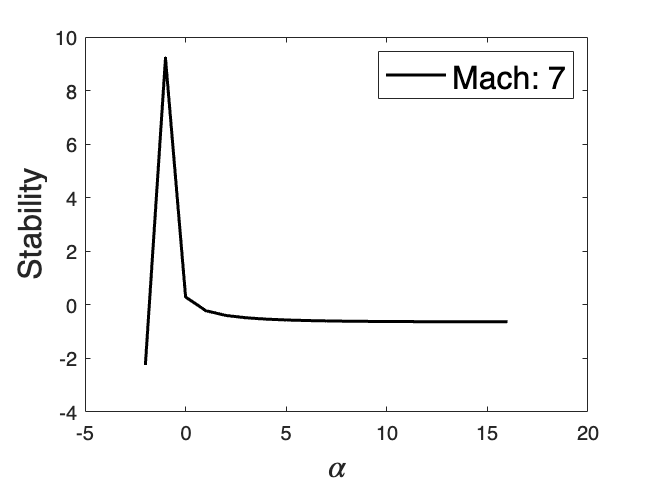


% Plotting

figure;
plot(AoA_sweep, SM, 'k', 'LineWidth', 1.5, 'DisplayName', sprintf('Mach: %d', M_inf));
xlabel('\alpha', 'FontSize', 16);
ylabel('Stability', 'FontSize', 16);
legend('FontSize', 16);

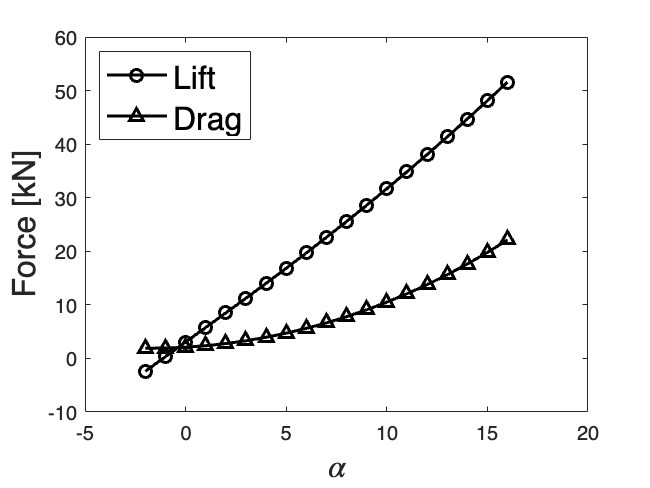


figure;
plot(AoA_sweep, Lift * 1e-3, 'ko-', 'LineWidth', 1.5, 'DisplayName', 'Lift');
hold on;
plot(AoA_sweep, Drag * 1e-3, 'k^-', 'LineWidth', 1.5, 'DisplayName', 'Drag');
xlabel('\alpha', 'FontSize', 16);
ylabel('Force [kN]', 'FontSize', 16);
legend('Fontsize', 16, Location="northwest");